## **Driver test program to check Clothoids library**

**Clothods list**

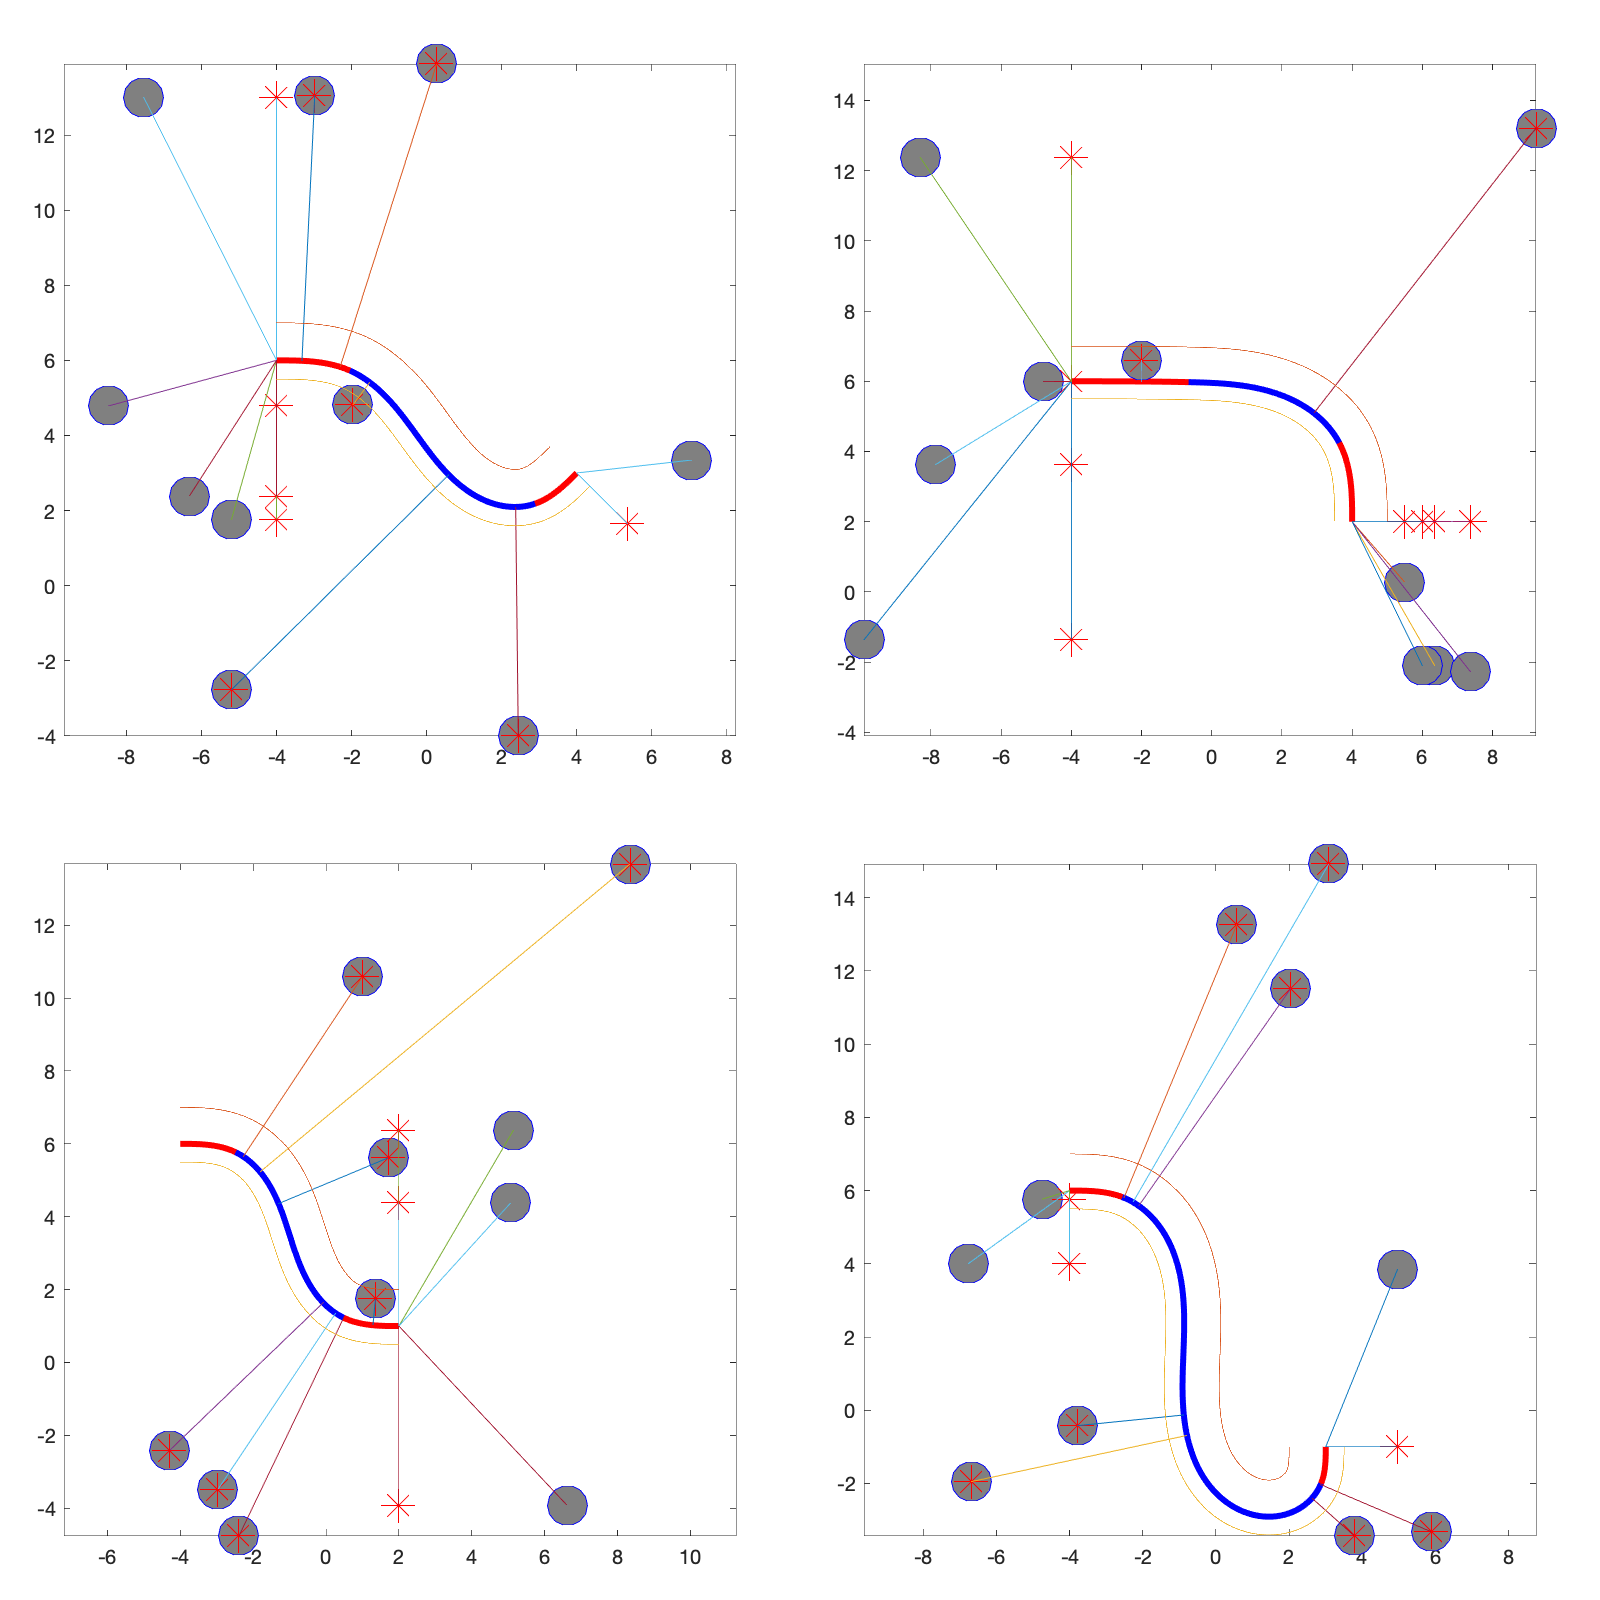

s =    6.884066633740671   8.684131894146061   3.429925288588462   1.792138979468964   2.418802843945519   6.436452154013057   8.684131894146061   8.684131894146061   7.138294161574056   7.971161784902995


t =   -5.816450694471492  -4.920997626667857   3.259020745134896   5.915394752475531  13.208572379993917  -5.834320163404695   5.376473217443854   3.387812821164117  -6.644043944416002   0.723112184680131


s =                    0  13.799611653842224   8.058517957993246   1.510870068453850   8.624270176266169   1.971744455692300                   0   1.785740285228363  13.355641037246055  14.845847427752620


t =   -1.989168029950045  -3.290410488668866  -2.913114898575360   8.073905910047197  -6.029955321086344   7.240019252794625  -0.233151294798859  10.675645414107844  -1.555360968752471  -1.963031856474190


s =                    0   7.085252036541854                   0  10.507003883442017  10.507003883442017  10.507003883442017                   0   1.991061653318824                   0  10.507003883442017


t =   -2.371723450729107  10.294295920003179  -7.363059433942951   1.498209294230048   2.346064413068659   3.373894107270192   6.385844152801788   0.599207861576833  -0.002795963273361   2.001369604486150


s =    9.806462929514868   7.887605357899406   0.677619962961160   1.711645922429284   2.604409526993642                   0                   0                   0                   0   5.854899955654581


t =   -1.919993588658672  -6.102254530918931   7.073484852596621   8.469604696011686  -0.746026935264388  -1.214947231999624  -4.245611803572457   7.001076928353239  -3.615064377595699  -8.143872213594832


close all;

% check constructors
x0     = [-4,-4,-4,-4];
y0     = [6,6,6,6];
x1     = [2,3,4,4];
y1     = [1,-1,2,3];
theta0 = 0;
theta1 = [0,pi/2,-pi/2,pi/4];

aa = 0.04;
bb = 0.5-2*aa;

figure('Position',[ 1 1 800 800]);

for kk=1:4

  switch(kk)
  case 1; subplot('Position',[aa aa bb bb]);
  case 2; subplot('Position',[aa+0.5 aa bb bb]);
  case 3; subplot('Position',[aa+0.5 aa+0.5 bb bb]);
  case 4; subplot('Position',[aa aa+0.5 bb bb]);
  end
  
  S = ClothoidList();
  iter = S.build_3arcG2( x0(kk), y0(kk), theta0, 0, x1(kk), y1(kk), theta1(kk), 0 );

  S.plot(400,{'Color','blue','LineWidth',3},{'Color','red','LineWidth',3});
  
  N = 10;

  x         = (-10 + 20 * rand(N,1)).';
  y         = (-5  + 20 * rand(N,1)).';
  
  [s,t]     = S.find_coord(x,y)

  [xx,yy]   = S.eval(s,t);
  [xxx,yyy] = S.eval(s);
  

  hold on;  
  plot( x,   y, 'ro', 'MarkerSize',20,'MarkerEdgeColor','blue','MarkerFaceColor',[0.5,0.5,0.5]);
  plot( xx, yy, 'b*', 'MarkerSize',15,'MarkerEdgeColor','red','MarkerFaceColor',[0.9,0.9,0.5]);
  plot( [x;xxx;xx], [y;yyy;yy] );
  
  sss = (0:S.length()/1000:S.length()).';
  [x,y] = S.eval( sss, 1 );
  plot( x, y );
  [x,y] = S.eval( sss, -0.5 );
  plot( x, y );

  axis equal;
  %
end